# Figure 2: S_Ilgn and S_Elgn

After Switch!!!

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];

S_EEInd = 3; S_IIInd = 2;
S_EE = S_EEtest(S_EEInd);
S_II = S_IItest(S_IIInd);

rE_L6 = 0.25;
rI_L6test  = [1.5 3 4.5 6] * rE_L6;
rI_L6Ind = 2; % 2 or 3; 2 for Figure2 in paper
rI_L6 = floor(rI_L6test(rI_L6Ind)*1000);

S_Ilgnhold = [1.5 2 2.5];%*S_Elgn S_Ilgnhold = [1.5 2 2.5 3];
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;

Panel2 = length(S_Elgntest);
Panel1 = length(S_Ilgnhold);

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

Fig1 = figure('Name','S_Ilgn_rI_L6','units','normalized','outerposition',[0 0 0.8 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .02],[.08 .08],[.10 .10]);

for S_IlgnInd = 1:length(S_Ilgnhold)
       
    for S_ElgnInd = 1:length(S_Elgntest)
        
        S_Elgn=S_Elgntest(S_ElgnInd);
        
        S_Ilgntest = S_Ilgnhold*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
                    
        CurrentPanelFile = sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end 
        
        % First axis for fr
        axes(ha(S_ElgnInd+Panel2*(S_IlgnInd-1)));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrEShow = CurrentFrE;
        CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrEShow(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        
        
        % set ticks, labels, titles, etc.
        if S_ElgnInd == 1
            set(gca,'fontsize',13)
            ylabel({sprintf('S^{Ilgn}/S^{Elgn}=%.1f',S_Ilgn/S_Elgn),'','S^{EI}/S^{EE}'},'FontSize',16)
        else
            set(gca,'yticklabel','')
        end
        
        if S_IlgnInd == 1
            title({sprintf('S^{Elgn}/S^{EE}=%.1f',S_Elgn/S_EE),''},'FontSize',16) 
        end
        
        
        if S_IlgnInd == length(S_Ilgntest)
            set(gca,'fontsize',13)
            xlabel('S^{IE}/S^{II}','FontSize',16);
        else
            set(gca,'xticklabel','')
        end
        
        axis square
        axis tight
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        hold on
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
        
        GreyHem = 0.5*ones(size(CurrentFrE));
        if NoFailWeight<0.11 || SIEWeight<1 % if impossible pattern show up on the left...
            FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
            
            
            
        end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        
        % Midpoint of Good Area
        CurrentFrEGA = CurrentFrE;
        CurrentFrEGA(CurrentFrE<=3 | CurrentFrE>=5 | ...
            CurrentFrI./CurrentFrE    <=3 | ...
            CurrentFrI./CurrentFrE    >=4.25) = nan;
        CurrentFrEGA(FailMap) = nan;
        GoodArea = (~isnan(CurrentFrEGA));
        
        GAratio = sum(double(GoodArea),'all')/(length(CurrentFrEGA(:)))
        if GAratio<0.007 % skip midpoint if too small
            disp('Good Area too small, Exit.')
        else
            [GA_SEIInd,GA_SIEInd,~] = find(GoodArea);
            MP_SEI = ContourData_7D.S_EItest(floor(mean(GA_SEIInd)))/S_EE;
            MP_SIE = ContourData_7D.S_IEtest(floor(mean(GA_SIEInd)))/S_II;
            scatter(MP_SIE,MP_SEI, 3000, 'k+','LineWidth',2)
        end
        
        
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        axis([min(ContourData_7D.S_IEtest/S_II) max(ContourData_7D.S_IEtest/S_II) ...
              min(ContourData_7D.S_EItest/S_EE) max(ContourData_7D.S_EItest/S_EE)])
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        sprintf('id1 = %.1f, id2 = %.1f, Fail = %.2f, SIEWgt = %.2f',...
                S_Ilgn/S_Elgn,S_Elgn/S_EE,NoFailWeight,SIEWeight)
            
        if S_ElgnInd == length(S_Elgntest)
            if S_IlgnInd == 1
                Pos1 = get(gca,'Position');
            elseif S_IlgnInd == length(S_Ilgntest)
                Pos2 = get(gca,'Position');
            end
        end
        
    end
end

GAratio = 0.0106

ans = 'id1 = 1.5, id2 = 1.5, Fail = 0.73, SIEWgt = 1.17'

GAratio = 0.0264

ans = 'id1 = 1.5, id2 = 2.0, Fail = 0.73, SIEWgt = 1.17'

GAratio = 0.0432

ans = 'id1 = 1.5, id2 = 2.5, Fail = 0.74, SIEWgt = 1.16'

GAratio = 0.0589

ans = 'id1 = 1.5, id2 = 3.0, Fail = 0.75, SIEWgt = 1.16'

GAratio = 0.0037

Good Area too small, Exit.


ans = 'id1 = 2.0, id2 = 1.5, Fail = 0.60, SIEWgt = 1.12'

GAratio = 0.0152

ans = 'id1 = 2.0, id2 = 2.0, Fail = 0.69, SIEWgt = 1.14'

GAratio = 0.0256

ans = 'id1 = 2.0, id2 = 2.5, Fail = 0.73, SIEWgt = 1.16'

GAratio = 0.0332

ans = 'id1 = 2.0, id2 = 3.0, Fail = 0.75, SIEWgt = 1.16'

GAratio = 0

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 1.5, Fail = 0.15, SIEWgt = 1.50'

GAratio = 0.0015

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 2.0, Fail = 0.27, SIEWgt = 1.37'

GAratio = 0.0054

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 2.5, Fail = 0.36, SIEWgt = 1.32'

GAratio = 0.0056

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 3.0, Fail = 0.43, SIEWgt = 1.30'

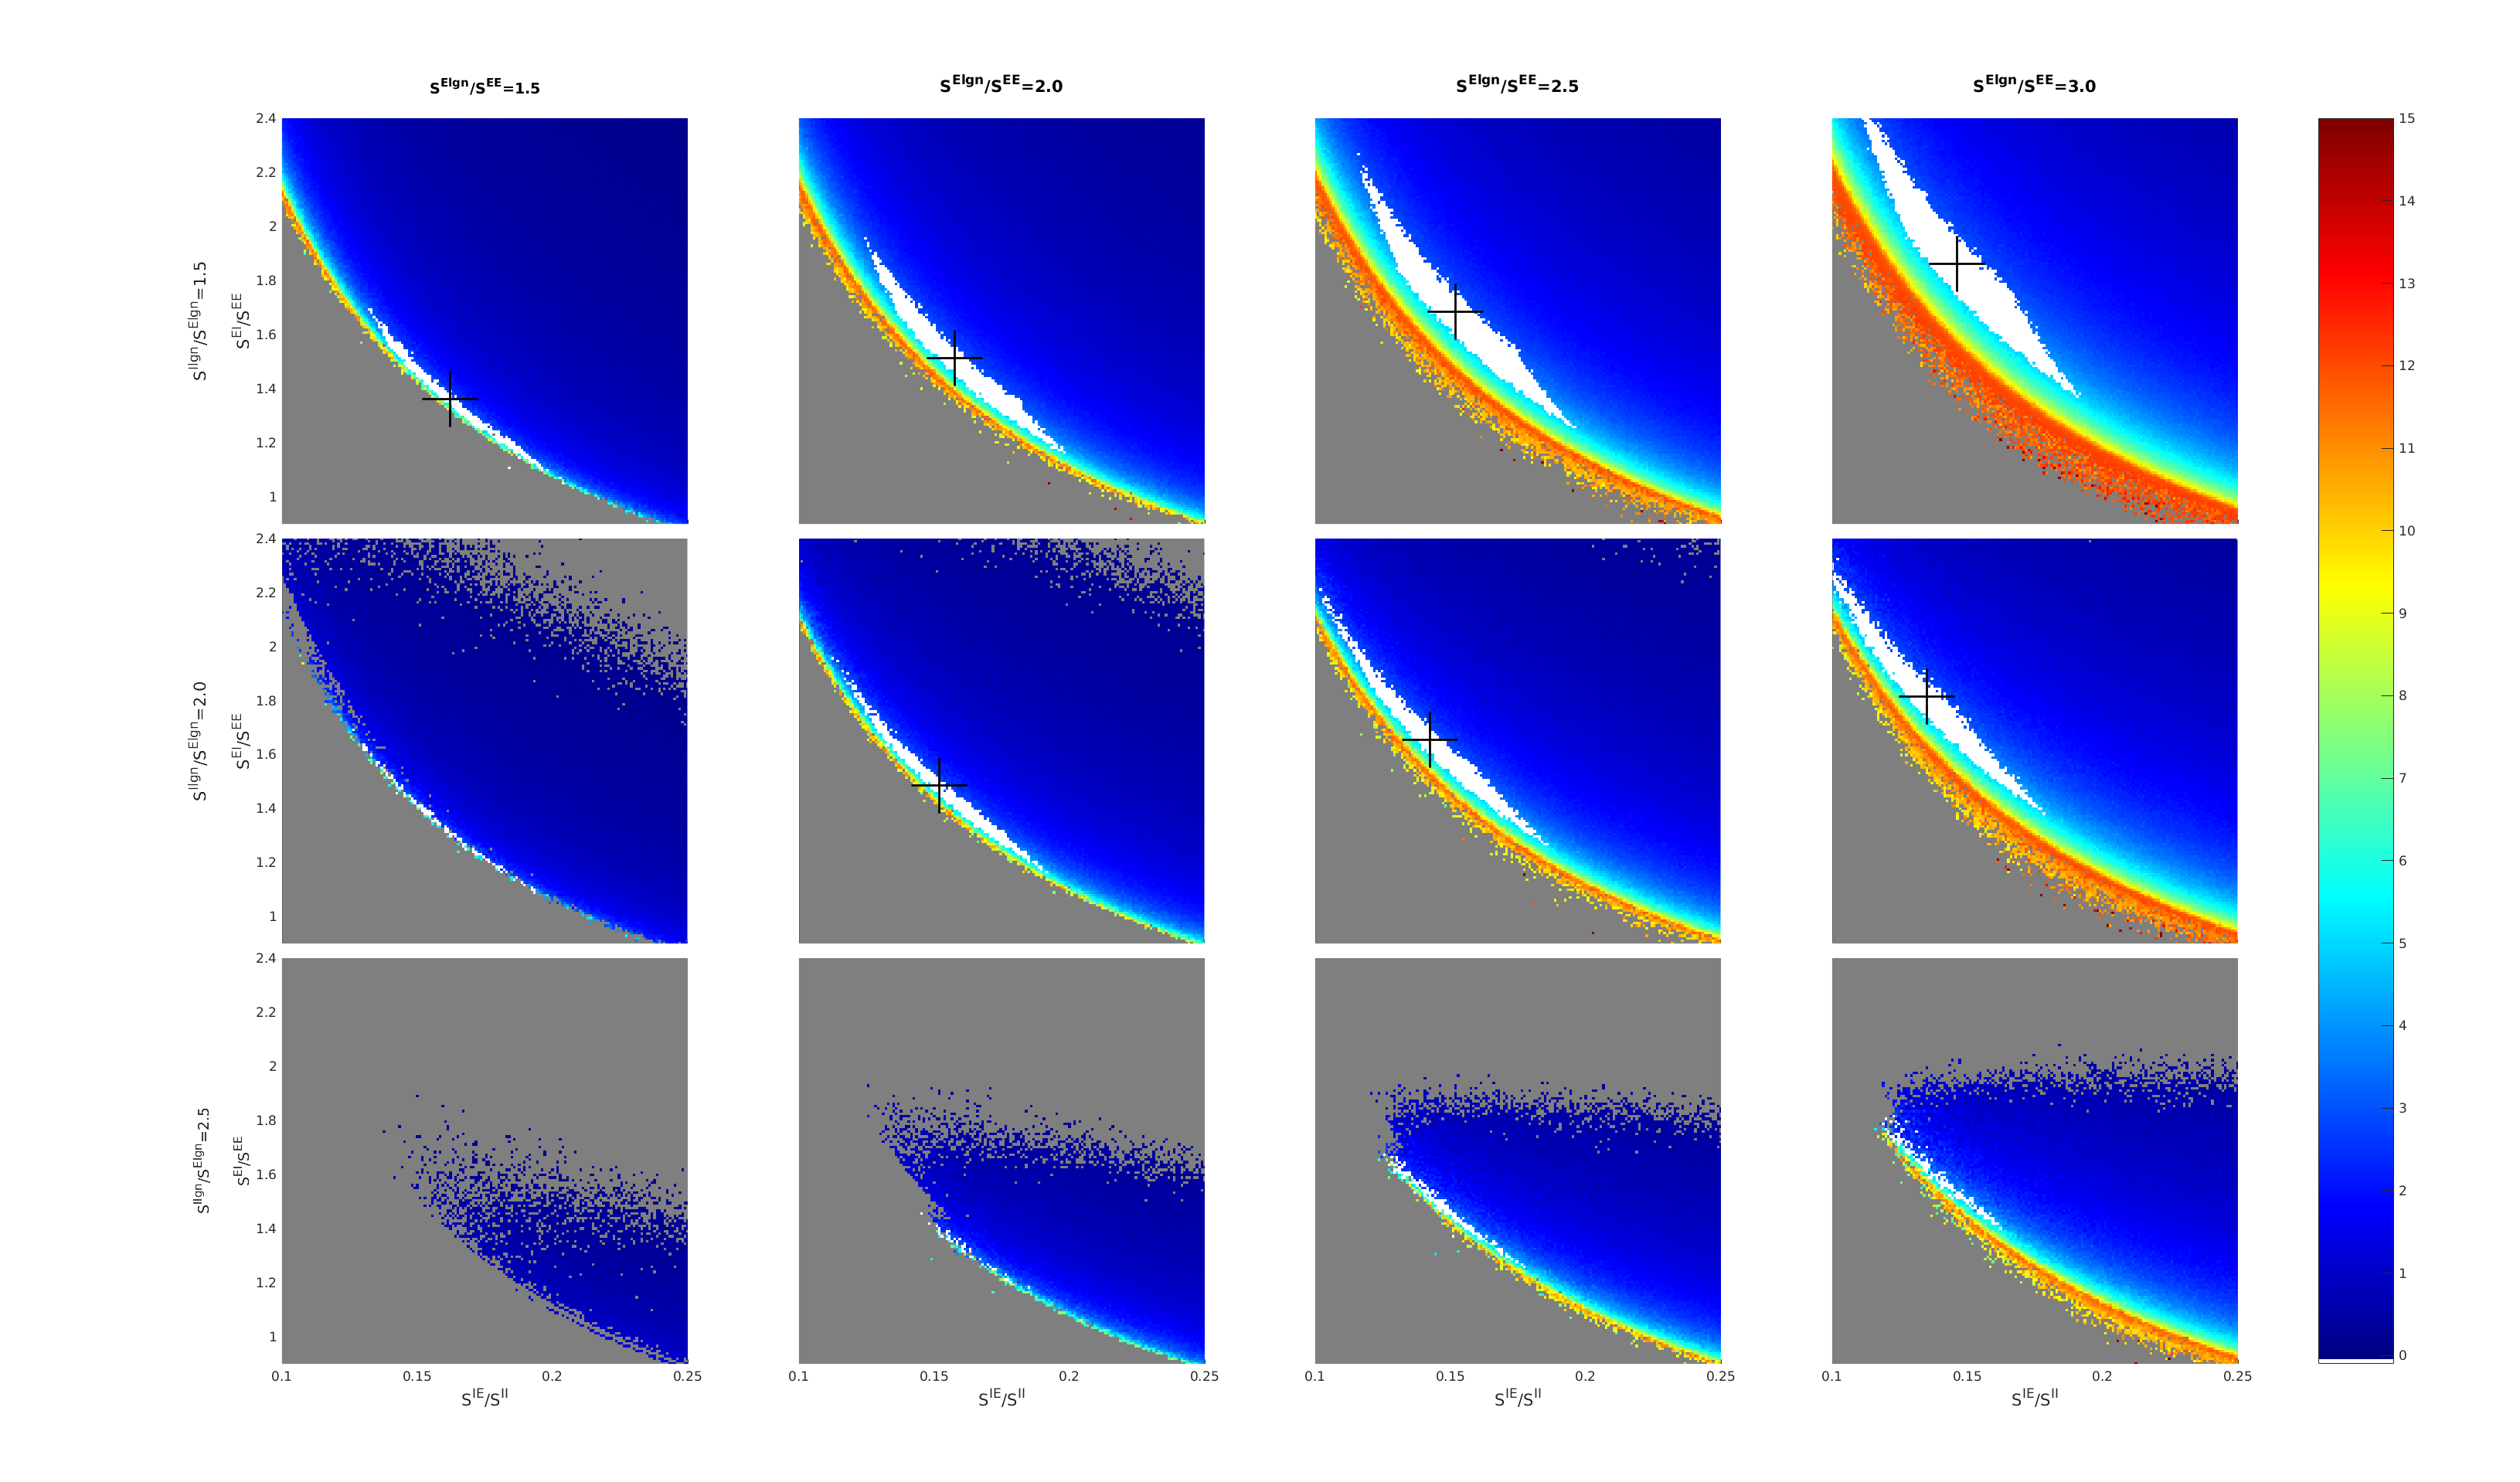


cbr = colorbar(ax1a, 'Position', [Pos2(1)+Pos2(3)+0.02  Pos2(2)  0.03  Pos1(2)+Pos1(4)-Pos2(2)]);
caxis([0 15])
set(cbr,'YTick',0:15,'FontSize',13)

Save figures

FigurePaperpath = [CurrentFolder '/Figure for Paper/'];
FigName1 = sprintf('Figure2_rIL6=%d',rI_L6);
savefig(Fig1,[FigurePaperpath FigName1 '.fig']);


Print Figs

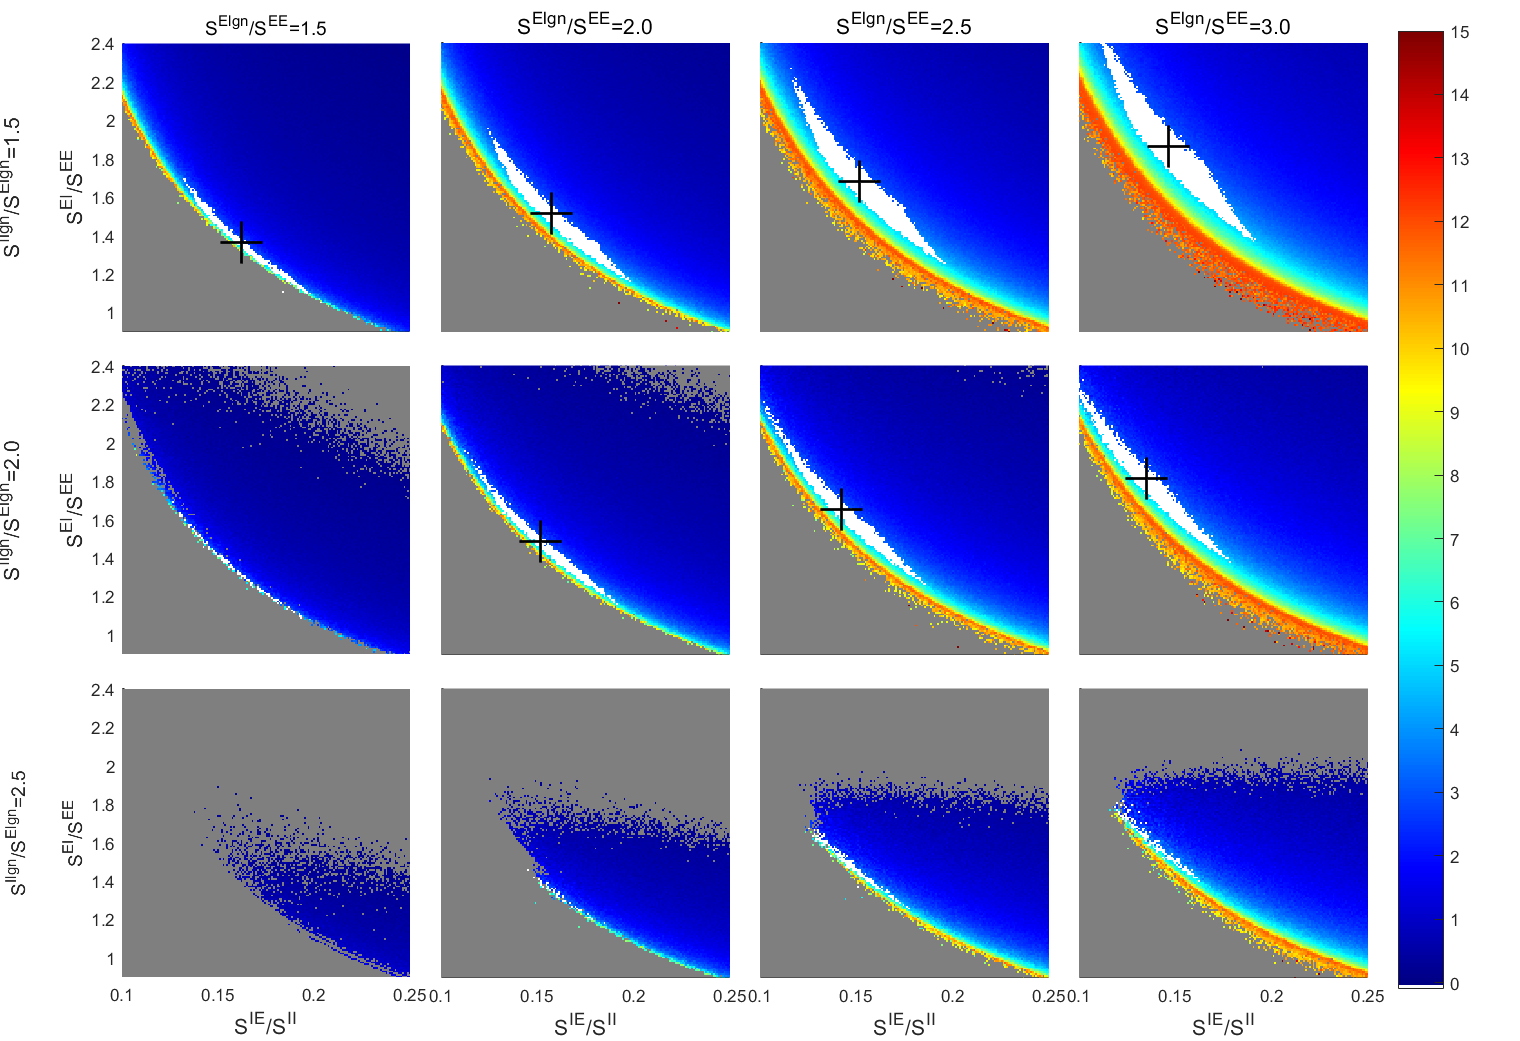

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [36,29];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[FigurePaperpath FigName1 '.pdf'],'Resolution',300)